% 计算主成分解释的变异性百分比。显示主成分空间中的数据表示。
% 
clear all
% 加载样本数据集。

load imports-85
% 数据矩阵 X 在第 3 列至第 15 列中有 13 个连续变量：
% 轴距、长度、宽度、高度、整备重量、引擎大小、缸径、冲程、压缩比、马力、峰值转速
% 、城市油耗和高速公路油耗。

% 计算由这些变量的主成分解释的变异性百分比。

[coeff,score,latent,tsquared,explained] = pca(X(:,3:15));

explained

explained =    64.3429
   35.4484
    0.1550
    0.0379
    0.0078
    0.0048
    0.0013
    0.0011
    0.0005
    0.0002


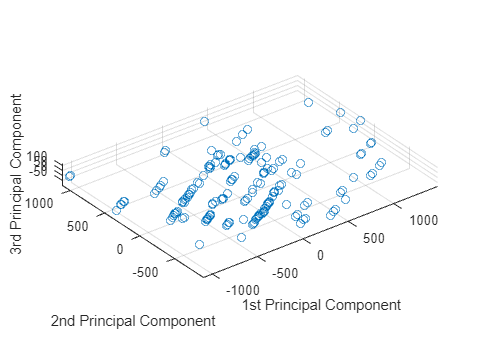



% 前三个成分解释所有变异性的 99.95%。
% 
% 可视化前三个主成分的空间中的数据表示。

scatter3(score(:,1),score(:,2),score(:,3))
axis equal
xlabel('1st Principal Component')
ylabel('2nd Principal Component')
zlabel('3rd Principal Component')


% 数据在第一主成分轴上具有最大变异性。在第一个轴的所有可能选择中，
% 这是有可能得到的最大方差。在剩余可供第二主成分轴使用的所有可能选择中，
% 该选择具有最大变异性。第三主成分轴具有第三大变异性，
% 它显著小于在第二主成分轴上的变异性。
% 第四至第十三主成分轴不值得研究，因为它们只解释数据中所有变异性的 0.05%。
% 
% 要跳过任何输出，您可以在对应的元素中使用 ~。例如，如果您不想得到 T 方值，请指定

% [coeff,score,latent,~,explained] = pca(X(:,3:15));